# Broad Cluster Growth Types

We see approximately four different types of growth:

(i) clusters do not form (mass-averaged cluster size remains <2 for all time)

(ii) clusters form slowly to an equilibrium value on the time scale of the simulation

(iii) clusters continue growing over the entire time scale of the simulation (really this is just a different time scale version of (ii))

(iv) A full spanning cluster rapidly forms, usually within the first 100 time steps of simulation

(v) anomalous growth -- one demonstration of a lag phase, one that basically just stays at the same size the whole way through (which is really a subset of (ii) with poor initial conditions)

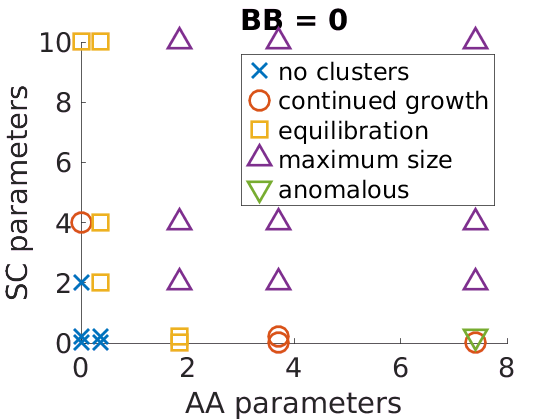

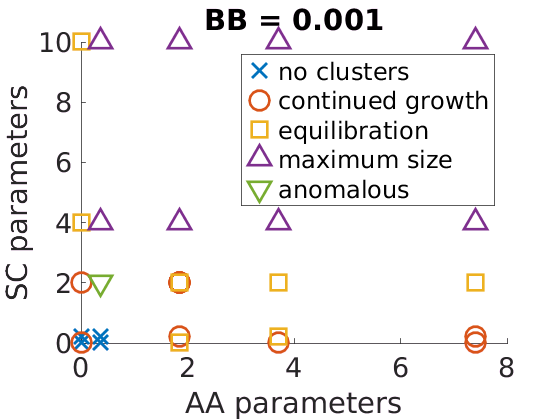

sigs = 4;
aas = 3;
scs = 3;
ctypemat = zeros(sigs*aas*scs,6); %AA, SC, sig, approx look, rad, concentration (molecules/nm^3)
row = 1;
for sig = [0.25,0.5,0.75,1.25]
    for aa = [2.5,5.0,7.5]
        for sc = [0.2,2,4]
            ctypemat(row,1) = aa;
            ctypemat(row,2) = sc;
            ctypemat(row,3) = 1.0;
            ctypemat(row,5) = sig;
            ctypemat(row,6) = 0.0027;
            row = row+1;
        end
    end
end

## Read in Data

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns/');
fbase = 'mols10000_';
%if exist(Name, 'file') == 7 -- folder exists
[contactMatrix,opticalMatrix,alignedMatrix,ctypemat] = readClusteringData2(fileLocation,fbase);

## Look at the final size, and the ratios of the contact/optical and contact/aligned final sizes

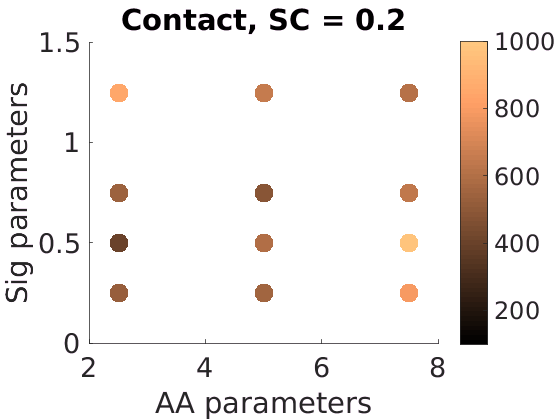

%contact final size
saveloc = '/home/rachael/Dropbox/Images/Research-Diffuse-12-4-17';
figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==0.2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(contactMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Contact, SC = 0.2')
saveas(gcf,[saveloc '/CCsizeSC02'],'pdf')
savefig([saveloc '/CCsizeSC02'])

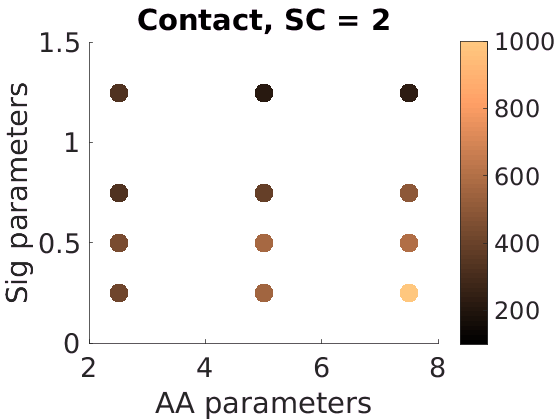


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(contactMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Contact, SC = 2')
saveas(gcf,[saveloc '/CCsizeSC2'],'pdf')
savefig([saveloc '/CCsizeSC2'])

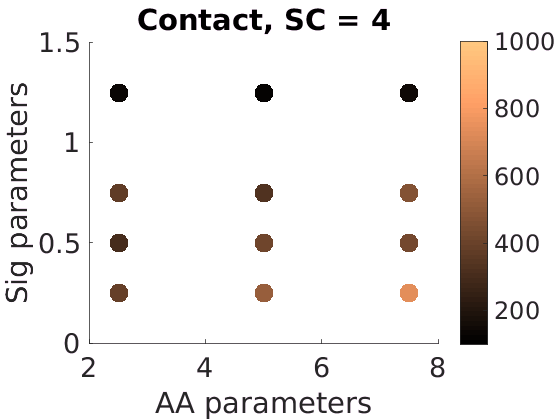


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==4);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(contactMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Contact, SC = 4')
saveas(gcf,[saveloc '/CCsizeSC4'],'pdf')
savefig([saveloc '/CCsizeSC4'])

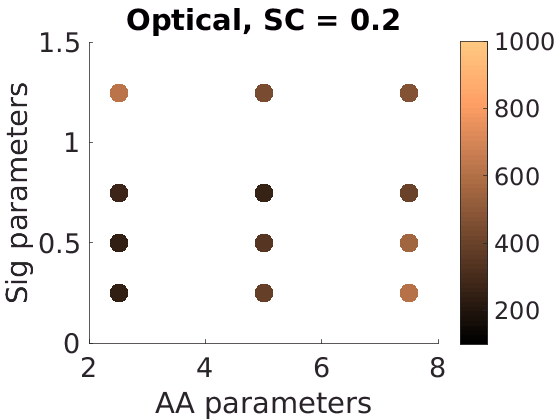


%optical final size
figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==0.2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(opticalMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Optical, SC = 0.2')
saveas(gcf,[saveloc '/OCsizeSC02'],'pdf')
savefig([saveloc '/OCsizeSC02'])

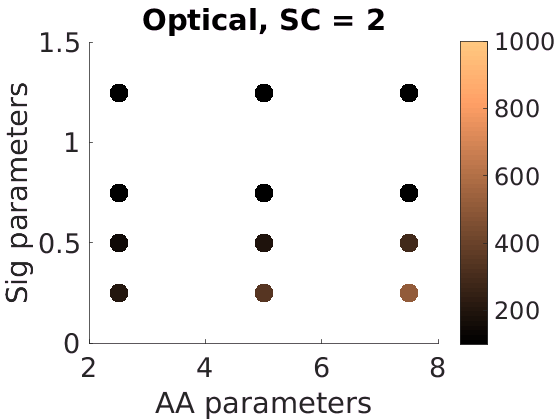


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(opticalMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Optical, SC = 2')
saveas(gcf,[saveloc '/OCsizeSC2'],'pdf')
savefig([saveloc '/OCsizeSC2'])

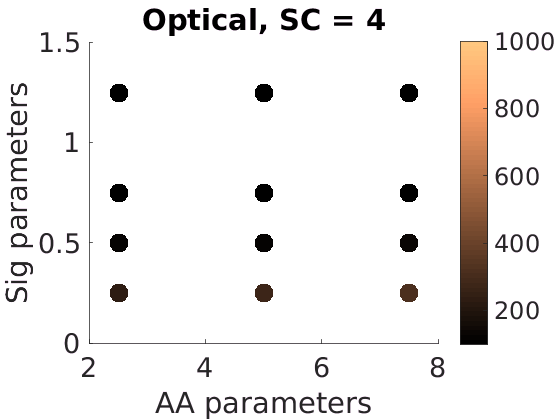


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==4);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(opticalMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Optical, SC = 4')
saveas(gcf,[saveloc '/OCsizeSC4'],'pdf')
savefig([saveloc '/OCsizeSC4'])

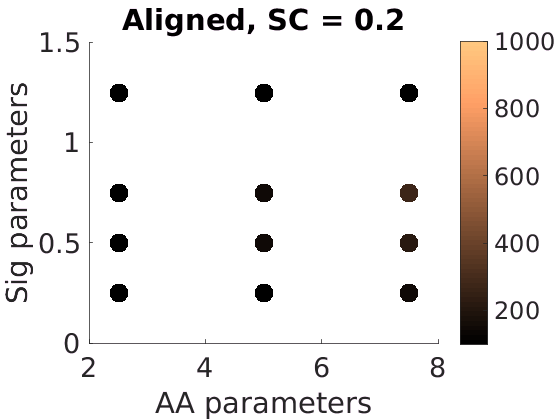


%aligned final size
figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==0.2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned, SC = 0.2')
saveas(gcf,[saveloc '/ACsizeSC02'],'pdf')
savefig([saveloc '/ACsizeSC02'])

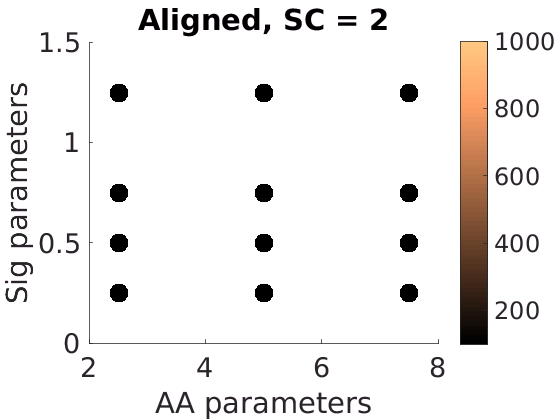


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned, SC = 2')
saveas(gcf,[saveloc '/ACsizeSC2'],'pdf')
savefig([saveloc '/ACsizeSC2'])

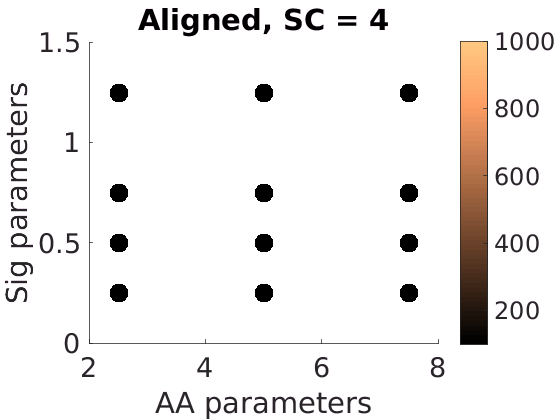


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==4);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)),'filled')
colorbar
caxis([100 1000])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned, SC = 4')
saveas(gcf,[saveloc '/ACsizeSC4'],'pdf')
savefig([saveloc '/ACsizeSC4'])

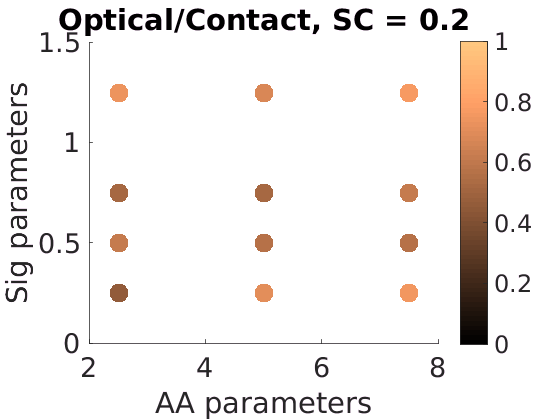

%optical/contact
figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==0.2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(opticalMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Optical/Contact, SC = 0.2')
saveas(gcf,[saveloc '/OCCsizeSC02'],'pdf')
savefig([saveloc '/OCCsizeSC02'])

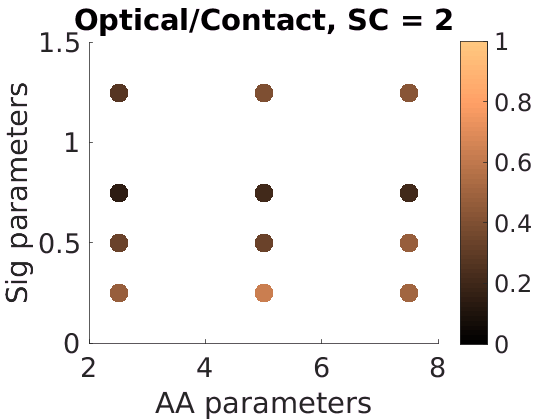


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(opticalMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Optical/Contact, SC = 2')
saveas(gcf,[saveloc '/OCCsizeSC2'],'pdf')
savefig([saveloc '/OCCsizeSC2'])

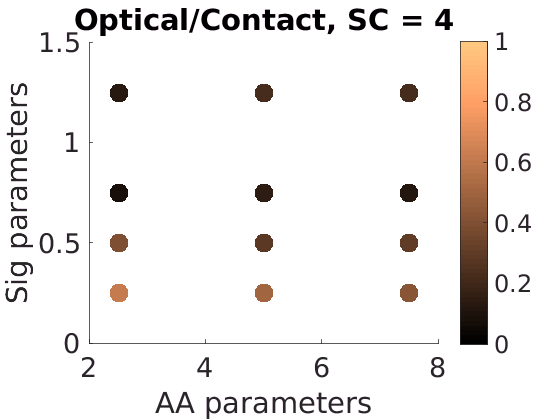


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==4);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(opticalMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Optical/Contact, SC = 4')
saveas(gcf,[saveloc '/OCCsizeSC4'],'pdf')
savefig([saveloc '/OCCsizeSC4'])

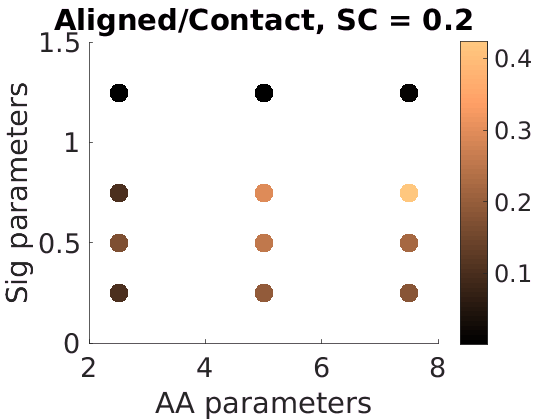

%aligned/contact

figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==0.2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned/Contact, SC = 0.2')
saveas(gcf,[saveloc '/ACCsizeSC02'],'pdf')
savefig([saveloc '/ACCsizeSC02'])

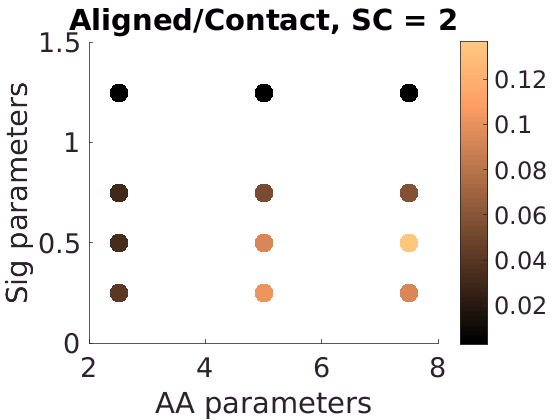


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned/Contact, SC = 2')
saveas(gcf,[saveloc '/ACCsizeSC2'],'pdf')
savefig([saveloc '/ACCsizeSC2'])

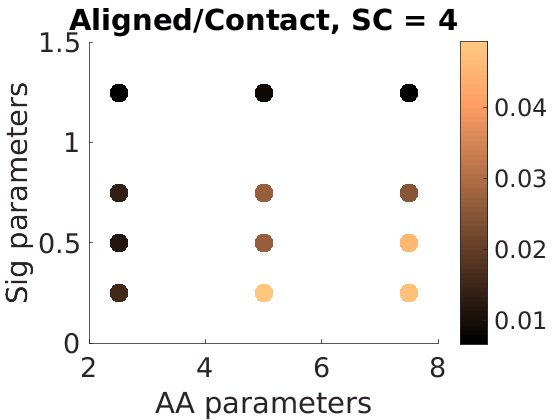


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==4);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned/Contact, SC = 4')
saveas(gcf,[saveloc '/ACCsizeSC4'],'pdf')
savefig([saveloc '/ACCsizeSC4'])

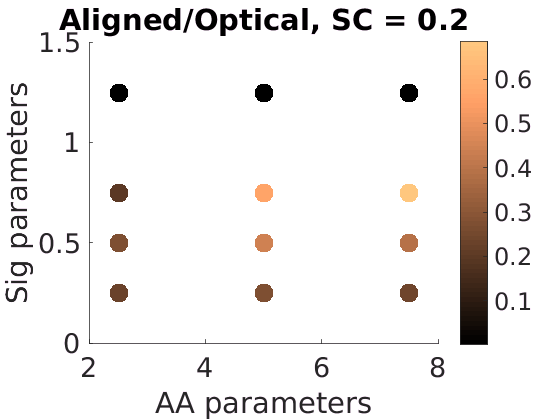

%aligned/optical
figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==0.2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)./opticalMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned/Optical, SC = 0.2')
saveas(gcf,[saveloc '/AOCsizeSC02'],'pdf')
savefig([saveloc '/AOCsizeSC02'])

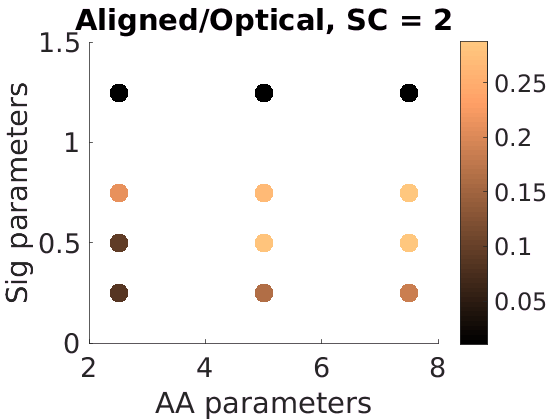


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==2);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)./opticalMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned/Optical, SC = 2')
saveas(gcf,[saveloc '/AOCsizeSC2'],'pdf')
savefig([saveloc '/AOCsizeSC2'])

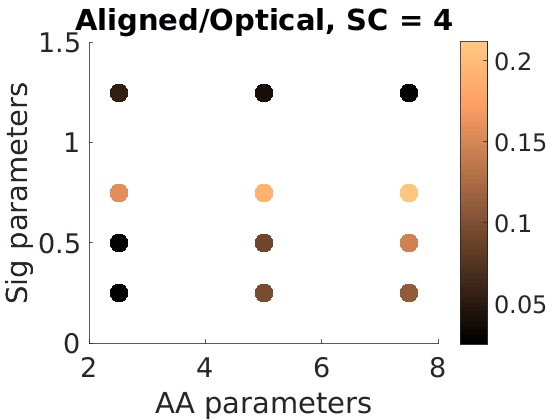


figure()
hold on
colormap copper
inot = find(ctypemat(:,2)==4);
scatter(ctypemat(inot,1),ctypemat(inot,5),200,(alignedMatrix(inot,8)./opticalMatrix(inot,8)),'filled')
colorbar
%caxis([0 1])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('Sig parameters')
title('Aligned/Optical, SC = 4')
saveas(gcf,[saveloc '/AOCsizeSC4'],'pdf')
savefig([saveloc '/AOCsizeSC4'])